## Final Project!!

clear
%import data 
Factors = table2struct(readtable('riskfactors.csv'));

% extract country code from the data set into a cell
% Factors.Country = categorical({Factors.Country});
countryNames = {Factors.Code};
% extract country code from the data set into a cell
countryCodes = {Factors.Code};




## Graphing based on user input

[vecnum, y] = size(Factors);
% ask user for country code
inputCode = input('Enter country code: ','s');

% extract a list of indeces where the data has the entered country code
listout = [];
for i = 1:vecnum
    if isequal({inputCode}, countryCodes(i))
        listout = [listout, i]; 
    end
end
if isempty(listout)
    error('Invalid country code. Please try again.')
end

% disp(listout)


## Actual Graphing Part

figure(1)
% initialize two empty lists to later store x y values of user's choice
x = zeros(1, length(listout));
yGraphAP = zeros(1, length(listout));
yGraphUW = zeros(1, length(listout));
yGraphHAP = zeros(1, length(listout));
yGraphHWF = zeros(1, length(listout));
yGraphSHS = zeros(1, length(listout));
yGraphVAD = zeros(1, length(listout));
yGraphZD = zeros(1, length(listout));
yGraphSG = zeros(1, length(listout));
yGraphNBF = zeros(1, length(listout));
yGraphLBW = zeros(1, length(listout));
yGraphCW = zeros(1, length(listout));
yGraphCT = zeros(1, length(listout));

sumTotalDeath = zeros(1, length(listout));

% extract years and different factors of the given indicies
for i = 1:length(listout)
    x(i) = [Factors(listout(i)).Year];
    % total number of death in the given year
    sumTotalDeath(i) = Factors(listout(i)).AmbientPollution + ...
        Factors(listout(i)).Underweight + Factors(listout(i)).HouseholdAirPollution + ...
        Factors(listout(i)).NoHandwashingFacility + Factors(listout(i)).SecondhandSmoke + ...
        Factors(listout(i)).VitaminADeficiency + Factors(listout(i)).ZincDeficiency + ...
        Factors(listout(i)).ShortGestation + Factors(listout(i)).Non_exclusiveBreastfeeding + ...
        Factors(listout(i)).LowBirthWeight + Factors(listout(i)).ChildWasting + ...
        Factors(listout(i)).ChildStunting;
    
    % calculate the percentage of each risk factors out of the total number
    % of death
    
    
    yGraphAP(i) = [Factors(listout(i)).AmbientPollution/sumTotalDeath(i)];
    yGraphUW(i) = [Factors(listout(i)).Underweight/sumTotalDeath(i)];
    yGraphHAP(i) = [Factors(listout(i)).HouseholdAirPollution/sumTotalDeath(i)];
    yGraphHWF(i) = [Factors(listout(i)).NoHandwashingFacility/sumTotalDeath(i)];
    yGraphSHS(i) = [Factors(listout(i)).SecondhandSmoke/sumTotalDeath(i)];
    yGraphVAD(i) = [Factors(listout(i)).VitaminADeficiency/sumTotalDeath(i)];
    yGraphZD(i) = [Factors(listout(i)).ZincDeficiency/sumTotalDeath(i)];
    yGraphSG(i) = [Factors(listout(i)).ShortGestation/sumTotalDeath(i)];
    yGraphNBF(i) = [Factors(listout(i)).Non_exclusiveBreastfeeding/sumTotalDeath(i)];
    yGraphLBW(i) = [Factors(listout(i)).LowBirthWeight/sumTotalDeath(i)];
    yGraphCW(i) = [Factors(listout(i)).ChildWasting/sumTotalDeath(i)];
    yGraphCT(i) = [Factors(listout(i)).ChildStunting/sumTotalDeath(i)];
end

% disp(x)
% disp(yGraph)
g = plot(x, yGraphAP, 'Color', [0, 0.4470, 0.7410]);
g(1).LineWidth = 2;
hold on
g = plot(x, yGraphUW, 'r-');
g(1).LineWidth = 2;
g = plot(x, yGraphHAP, 'm-');
g(1).LineWidth = 2;
g = plot(x, yGraphHWF, 'c-');
g(1).LineWidth = 2;
g = plot(x, yGraphSHS, 'g-');
g(1).LineWidth = 2;
g = plot(x, yGraphVAD, 'Color', [1.0 0.4 0.8]);
g(1).LineWidth = 2;
g = plot(x, yGraphZD, 'Color', [0.8 0.6 1.0]);
g(1).LineWidth = 2;
g = plot(x, yGraphSG, 'Color', [1.0 0.6 0.4]);
g(1).LineWidth = 2;
g = plot(x, yGraphNBF, 'Color', [0.2 0.6 1.0]);
g(1).LineWidth = 2;
g = plot(x, yGraphLBW, 'Color', [0.8500, 0.3250, 0.0980]);
g(1).LineWidth = 2;
g = plot(x, yGraphCW, 'Color', [0.9290, 0.6940, 0.1250]);
g(1).LineWidth = 2;
g = plot(x, yGraphCT, 'Color', [0.4940, 0.1840, 0.5560]);
g(1).LineWidth = 2;

grid on
xlabel('Years');
ylabel('Percentage of Death')
t = sprintf('Percentage of Total Death Caused by Associated Risk Factors in %s',Factors(listout(1)).Country);
title(t);
legend('Ambient Pollution', 'Underweight', 'Household Air Pollution', ...
    'No Handwashing Facility', 'Secondhand Smoke', 'Vitamin A Deficiency', ...
    'Zinc Deficiency', 'Short Gestation', 'Non Exclusive Breastfeeding',...
    'Low Birth Weight', 'Child Wasting', 'Child Stunting');
fprintf(['Here a graph of the percentage of total death caused by associated' ...
    'rick factors in %s.\n'], Factors(listout(1)).Country)

Here a graph of the percentage of total death caused by associatedrick factors in China.


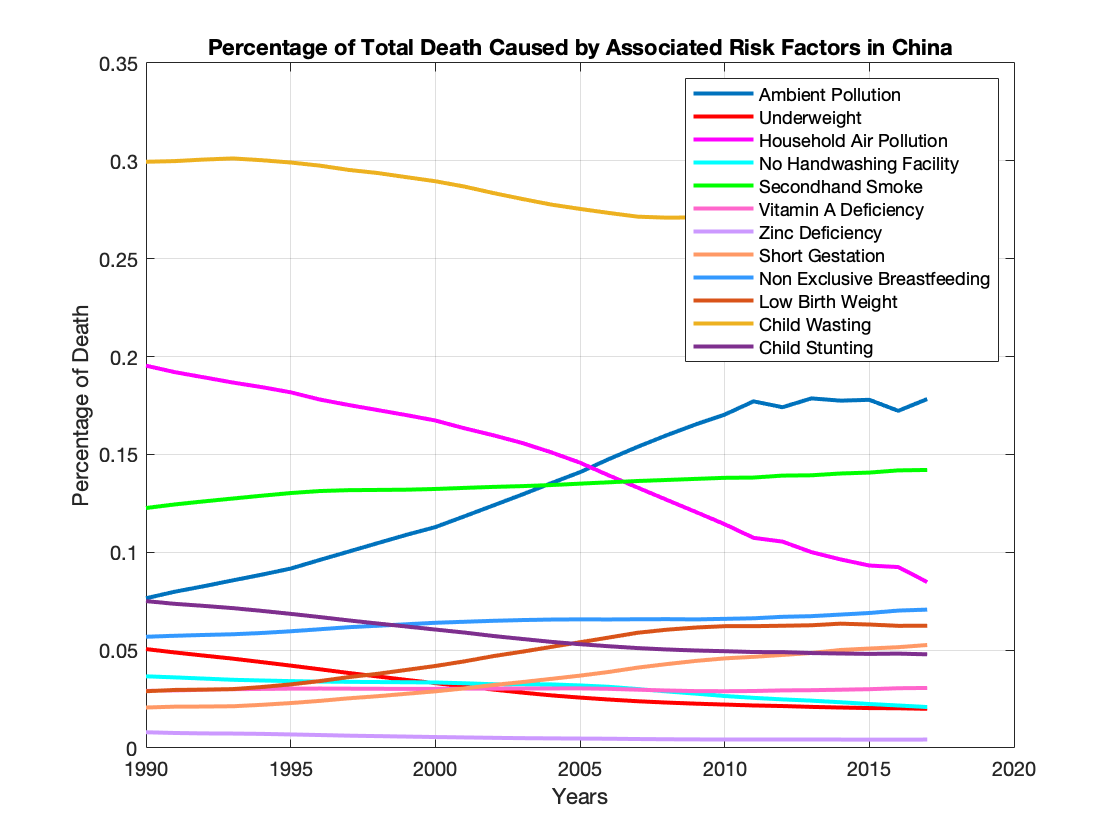


hold off

## Prediction

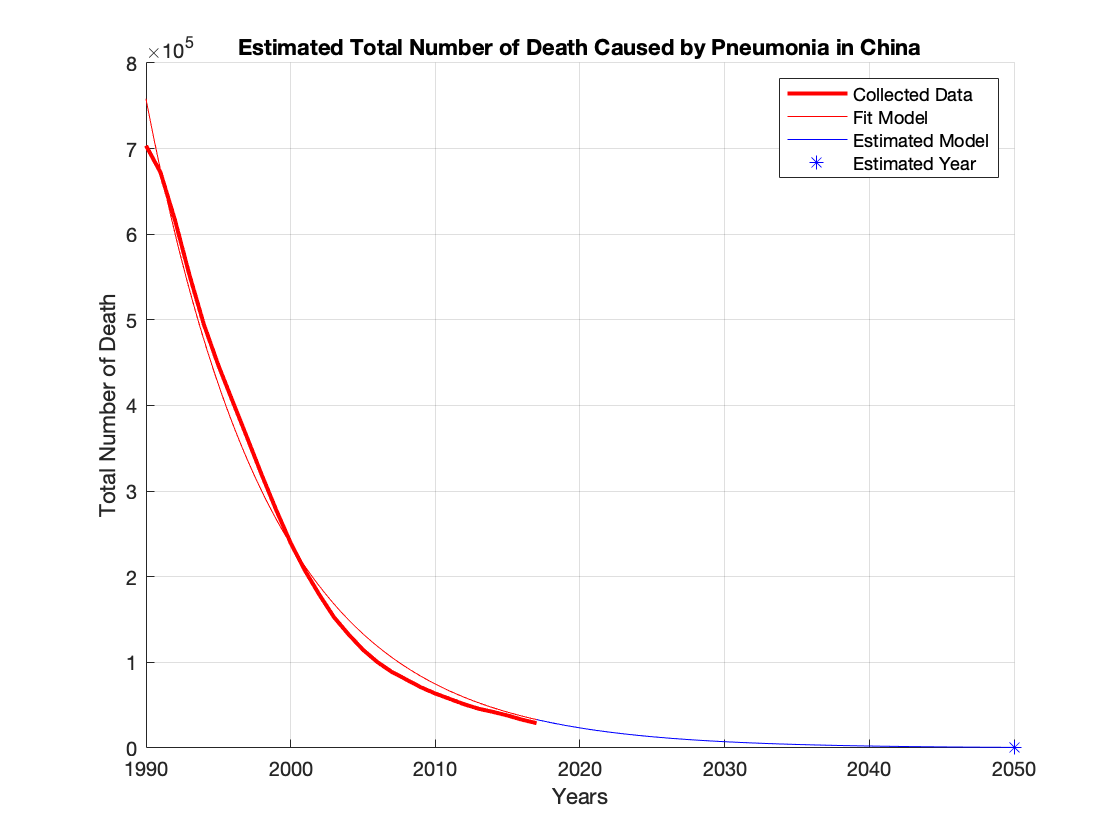

% use polyfit on the total sum of death to predict future trends
clf
sumTotalDeath;

% ask for user input for estimated year
estyear = input(['Enter the year of total number of death caused by pneumonia you want to ' ...
    'estimate: ']);

% look for the year with the max number of death for a better estimation
for i = 1:length(sumTotalDeath)
    if isequal(sumTotalDeath(i), max(sumTotalDeath))
        maxindex = i;
    end
end


% s = plot(x, sumTotalDeath, 'b');
% s(1).LineWidth = 2;
hold on 
fitfunc = fit(x(maxindex:end)', sumTotalDeath(maxindex:end)', 'exp1');
% est = polyval(fitfunc, [x x(end):estyear]);

% graph original data and the best fit model
e = plot(fitfunc, x, sumTotalDeath, 'r-');
e(1).LineWidth = 2;

% Graph estimated year based on the model
plot(x(end):estyear, fitfunc(x(end):estyear), 'b-');

plot(estyear, fitfunc(estyear), 'b*');

legend('Collected Data', 'Fit Model', 'Estimated Model', 'Estimated Year');
grid on
xlabel('Years');
ylabel('Total Number of Death')
t = sprintf('Estimated Total Number of Death Caused by Pneumonia in %s',Factors(listout(1)).Country);
title(t);

hold off

fprintf('The estimated total number of death caused by pneumonia in %d is %.3f.\n', estyear, fitfunc(estyear))

The estimated total number of death caused by pneumonia in 2050 is 725.108.


## polyfit doesnt give a good model

% we ran through the length of the list of index instead of using the index
% listed

% figure out fit function instead of polyfit

% starting the exponential estimation from the maximum value of total
% number of death to form a better fitting model
